# M2 edge-sensor control loop implementation test

.

## Preamble

### Load LOM data

filename1 = fullfile(im.lfFolder,'ceo-data','lom_tt_dt.mat');
load(filename1,'D_seg_tt');
fprintf('\nTT sensitivity matrix loaded from \n%s\n',filename1);


TT sensitivity matrix loaded from 
/Users/rromano/Workspace/gmt-data/ceo-data/lom_tt_dt.mat


filename2 = fullfile(im.lfFolder,'ceo-data','D_seg_piston_dt.mat');
load(filename2,'D_seg_piston');
fprintf('Piston sensitivity matrix loaded from \n%s\n',filename2);

Piston sensitivity matrix loaded from 
/Users/rromano/Workspace/gmt-data/ceo-data/D_seg_piston_dt.mat


filename3 = fullfile(im.lfFolder,'ceo-data','rbm2gtt.mat');
load(filename3,'rbm2gtt');
fprintf('Global TT sensitivity matrix loaded from \n%s\n',filename3);

Global TT sensitivity matrix loaded from 
/Users/rromano/Workspace/gmt-data/ceo-data/rbm2gtt.mat


Ts = 1/8e3;     % Simulation sampling period

## M2 ES Interaction matrix

### Load telescope structural model

ModelFolder = fullfile(im.lfFolder,"20230131_1605_zen_30_M1_202110_ASM_202208_Mount_202111");
if(~exist('gainMatrix','var') || 0)
    % Static solution gain matrix
    staticSolFile = fullfile(ModelFolder,"static_reduction_model.mat");
    try
        load(staticSolFile,'gainMatrixMountControlled');
        gainMatrix = gainMatrixMountControlled;
    catch, load(staticSolFile,'gainMatrix');
    end
    fprintf('Static gain matrix loaded from \n%s\n', ModelFolder);
end

### Compute M2ES interaction matrix from telescope model

Let $D_\text{m2es} \in \mathbb{R}^{48 \times 42}$ be the interaction matrix representing the static response of the M1 edge sensor distance measurements to M1 rigid body motions in the local coordinate system.

% Indices of M2 force inputs
in_m2p_mc = inputTable{'MC_M2_SmHex_F',"indices"}{1}(1:2:end);	%macrocell side
in_m2p_m2 = inputTable{'MC_M2_SmHex_F',"indices"}{1}(2:2:end);	%mirror segment side
% Indices of M2 POS displacements
out_m2p_mc = outputTable{'MC_M2_SmHex_D',"indices"}{1}(1:2:end);	%macrocell side
out_m2p_m2 = outputTable{'MC_M2_SmHex_D',"indices"}{1}(2:2:end);	%mirror seg side
% M2 reference body (RB) RBM (local CS) output indices
out_asm_RB = outputTable{'MC_M2_RB_6D',"indices"}{1};
% M2 ES output indices
out_m2es = outputTable{'M2_edge_sensors',"indices"}{1};

% M2 POS 6F -> M2 POS 6D
K_m2p = gainMatrix(out_m2p_mc,in_m2p_mc) -gainMatrix(out_m2p_mc,in_m2p_m2) ...
        - gainMatrix(out_m2p_m2,in_m2p_mc) +gainMatrix(out_m2p_m2,in_m2p_m2);

% M2 POS 6F -> ASM RB
K_m2p_2_asm = gainMatrix(out_asm_RB,in_m2p_mc) - gainMatrix(out_asm_RB,in_m2p_m2);
% ASM RB -> M2P 6D
K_asm_2_m2p = K_m2p / K_m2p_2_asm;
% M2 POS 6F -> M2ES
K_m2p_2_es = gainMatrix(out_m2es,in_m2p_mc)-gainMatrix(out_m2es,in_m2p_m2);
% ASM RB -> M2ES
K_asm_2_es = K_m2p_2_es / K_m2p_2_asm;

### Plot M2ES interaction matrix and its singular values

Below, we show the M2 ES interaction matrix (left-hand plot) and, at the right, its singular values compared to the singular values of a matrix built from the first 36 columns of $D_\text{m2es}$, corresponding to the off-axis segment rigid-body motions.

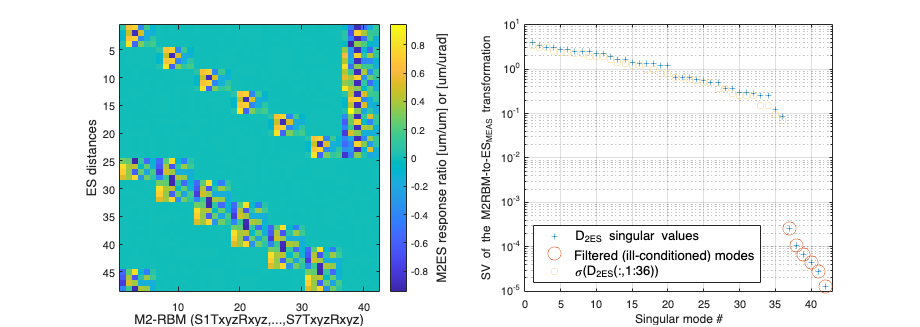

figure; set(gcf,'Position',[833   323   900   320]);%360   277   560   420
subplot(121)
imagesc(K_asm_2_es);
ylabel('ES distances','Fontsize',12);
xlabel('M2-RBM (S1TxyzRxyz,...,S7TxyzRxyz)','Fontsize',12);
cbar = colorbar;
ylabel(cbar,'M2ES response ratio [um/um] or [um/urad]','Fontsize',12)

[~,Ses,~] = svd(K_asm_2_es, "econ");
subplot(122)
sigma = diag(Ses);
semilogy(sigma,'+'); hold on;
Tmodes = 37:42; semilogy(Tmodes, sigma(Tmodes),'o','MarkerSize',12);
ylabel('SV of the M2RBM-to-ES_{MEAS} transformation');
xlabel('Singular mode #');

[~,Ses_,~] = svd(K_asm_2_es(:,1:36), "econ");
sigma_ = diag(Ses_);
semilogy(sigma_,'s'); hold on;
legend('D_{2ES} singular values','Filtered (ill-conditioned) modes',...
    '\sigma(D_{2ES}(:,1:36))','fontsize',12,'location','southwest');
grid on; hold off; xlim([0,43]);

### M2 ES reconstruction

There are at least two reconstructors $R_\text{2es}$. One is obtained through the truncated SVD inversion of the M2ES interaction matrix (TSVD rec). The second considers the inverse of an interaction matrix composed of columns corresponding to the outer axis segments (OAseg rec).

Below, we show the map $R_\text{2es}D_\text{2es}$ mapping the actual M2 rigid-body motions into its estimated (reconstructed) values for each reconstructor.

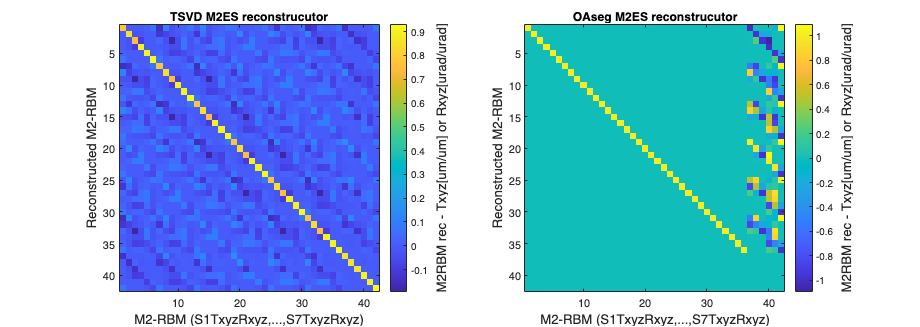

Rm2es_tsvd = pinv(K_asm_2_es, 1e-2);
Rm2es_oaseg = [pinv(K_asm_2_es(:,1:36), 1e-2); zeros(6,48)];
figure; set(gcf,'Position',[833   323   900   320]);%360   277   560   420
subplot(121)
imagesc(Rm2es_tsvd*K_asm_2_es);
ylabel('Reconstructed M2-RBM','Fontsize',12);
xlabel('M2-RBM (S1TxyzRxyz,...,S7TxyzRxyz)','Fontsize',12);
title('TSVD M2ES reconstrucutor')
cbar = colorbar;
ylabel(cbar,'M2RBM rec - Txyz[um/um] or Rxyz[urad/urad]','Fontsize',12)
subplot(122)
imagesc(Rm2es_oaseg*K_asm_2_es);
ylabel('Reconstructed M2-RBM','Fontsize',12);
xlabel('M2-RBM (S1TxyzRxyz,...,S7TxyzRxyz)','Fontsize',12);
title('OAseg M2ES reconstrucutor')
cbar = colorbar;
ylabel(cbar,'M2RBM rec - Txyz[um/um] or Rxyz[urad/urad]','Fontsize',12)

We can also evaluate the effect of the reconstructor limitations on the feedforward correction by projecting the estimated M2 rigid-body motion onto the segment TT and piston at the exit pupil using the linear optical model $L_\text{ttp}$, that is $L_\text{ttp} R_\text{2es} D_\text{2es} \in \mathbb{R}^{21 \times 42}$.

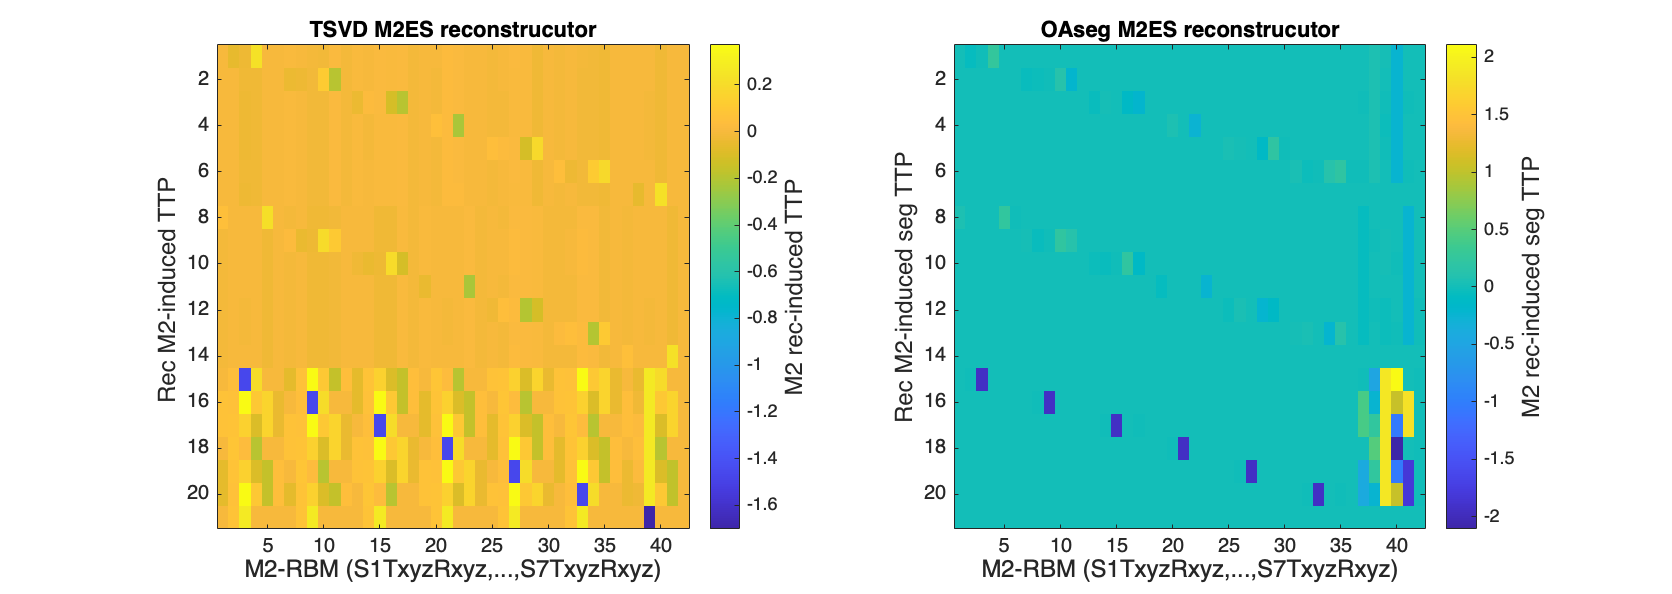

figure; set(gcf,'Position',[833   323   900   320]);%360   277   560   420    
subplot(121)
imagesc([D_seg_tt(:,(1:42)+42);D_seg_piston(:,(1:42)+42)]*Rm2es_tsvd*K_asm_2_es);
title('TSVD M2ES reconstrucutor')
ylabel('Rec M2-induced TTP ','Fontsize',12);
xlabel('M2-RBM (S1TxyzRxyz,...,S7TxyzRxyz)','Fontsize',12);
cbar = colorbar;
ylabel(cbar,'M2 rec-induced TTP','Fontsize',12)
subplot(122)
imagesc([D_seg_tt(:,(1:42)+42);D_seg_piston(:,(1:42)+42)]*Rm2es_oaseg*K_asm_2_es);
title('OAseg M2ES reconstrucutor')
ylabel('Rec M2-induced seg TTP','Fontsize',12);
xlabel('M2-RBM (S1TxyzRxyz,...,S7TxyzRxyz)','Fontsize',12);
cbar = colorbar;
ylabel(cbar,'M2 rec-induced seg TTP','Fontsize',12)

The first 14 outputs are the segment tip-tilt at the focal plane, and the last seven stand for the segment piston.